# Метод установления решения задачи Дирихле для уравнения Пуассона. Схема переменных направлений Вариант 12.

## Условие

Найти решение задачи 


$$Lu = -f (x,y)$$



$$Lu = \frac{\partial }{\partial x}\big((1+\frac{x}{2})\frac{\partial u}{\partial x}\big) + \frac{\partial^2 u}{\partial y^2},\ 0 < x < 1, 0 < y < 1$$



$$u(x,y)\vert_{\Gamma} = \mu(x,y)$$


используя схему переменных направлений. 

Отладить решение на функции $u^*(x,y) = xy^2(1+y)$

## Начальные данные

addpath("methods\","norms\","utils\")

global f;
global mu_bot;
global mu_top;
global mu_left;
global mu_right;
global lx;
global ly;
global eps;
global q;
global p;
global pk;
global c1;
global c2;
global d12;
global U_exact;
global k_max;
syms x;
syms y;


lx = 1;
ly = 1;
eps = 0.001;
q = 1;
p = 1+x/2;
pk = 1;
c1 = 1;
c2 = 1.5;
d12 = 1;
U_exact = x*y^2*(1+y);
[f, mu_bot, mu_top, mu_left, mu_right] = initConditions(U_exact);
     

N = 20;
M = 20; 
k_max = 50;
par = 3;    

## Решение

Схема переменных направлений:
1. Мера аппроксимации точного решения ||F-Au*||:


norm1 =      2.442490654175344e-13


2. Мера аппроксимации нулевого приближения ||F-Au0||:


norm2 =      1.798930687500000e+03


3. Оценка количества итераций


norm3 =     22


4. Спектральный радиус матрицы перехода:
-


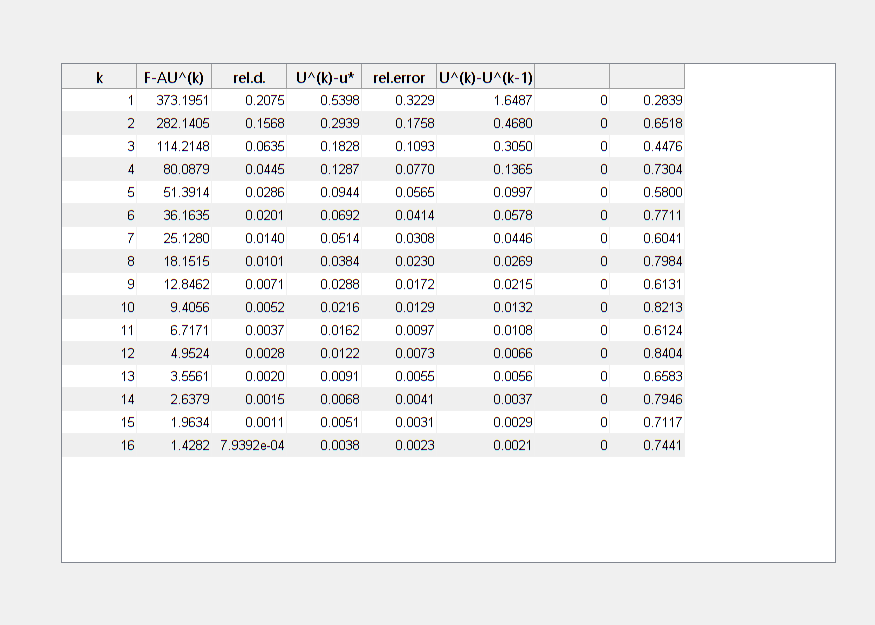

6. Приближенное решение на крупной сетке:


ans =                    0                   0                   0                   0                   0                   0
                   0   0.008501461700725   0.017543068042359   0.027255999612799   0.037529189143998   0.048000000000000
                   0   0.043020521682261   0.086916002096115   0.131898935436826   0.177789408272674   0.224000000000000
                   0   0.113417958411043   0.227712135898640   0.343095332747911   0.459387376368638   0.576000000000000
                   0   0.229291667598643   0.459128295538981   0.689642233959460   0.920721425363324   1.152000000000000
                   0   0.400000000000000   0.800000000000000   1.200000000000000   1.600000000000000   2.000000000000000


7. Таблица точного решения на крупной сетке:


ans =                    0                   0                   0                   0                   0                   0
                   0   0.009600000000000   0.019200000000000   0.028800000000000   0.038400000000000   0.048000000000000
                   0   0.044800000000000   0.089600000000000   0.134400000000000   0.179200000000000   0.224000000000000
                   0   0.115200000000000   0.230400000000000   0.345600000000000   0.460800000000000   0.576000000000000
                   0   0.230400000000000   0.460800000000000   0.691200000000000   0.921600000000000   1.152000000000000
                   0   0.400000000000000   0.800000000000000   1.200000000000000   1.600000000000000   2.000000000000000


u_dir_var = DirectionVariablesMethod(N, M);